# **Modélisation mathématiques du dirigeable**

clc; clear;

## Données :

g = 9.80665;
rho = 1.225;
diameter = 12.7*10^(-2);
radius = diameter/2;
m_struct = 3;
v_struct = 7;
key = ["gravity", "rho", "diameter", "m_struct", "v_struct"];
value = [g, rho, diameter, m_struct, v_struct];
data = containers.Map(key, value);

% Axes du dirigeable
x_m = [1; 0; 0];
y_m = [0; 1; 0];
z_m = [0; 0; 1];

key_axes_m = {'x_m', 'y_m', 'z_m'};
value_axes_m = {x_m, y_m, z_m};
data_axes = containers.Map(key_axes_m, value_axes_m);

% angle du servomoteur
angle = 0;

## Import workbench data

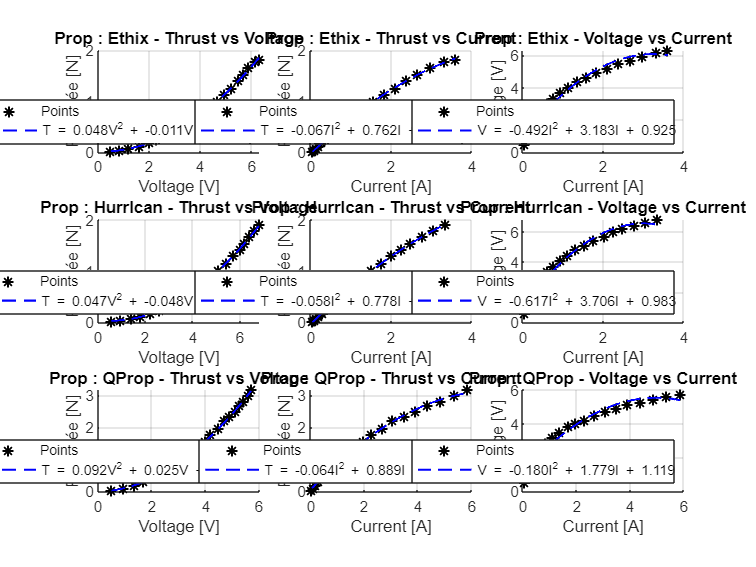


% Définir le répertoire de travail courant
current_folder = pwd;
data_folder = fullfile(current_folder, 'data');
test_Bench_data = load(fullfile(data_folder, "testBench_motor.mat"));

% Structure pour stocker les coefficients
coefficients = struct();

PropName = ["Ethix", "HurrIcan", "QProp"];
coefficients = FindInterpCoeff(PropName, g, test_Bench_data, coefficients);


output_file = fullfile(data_folder, 'coefficients.mat');
save(output_file, 'coefficients');


## Classe MotorSimulation

voltage_value = 6.3

voltage_value = 6.3000

MotSim = MotorSimulation(PropName(1), coefficients, angle, data_axes, voltage_value)

MotSim =   MotorSimulation with properties:

      MotorName: "Ethix"
          Coeff: [1×1 struct]
       AngleRot: 0
           Axes: [3×1 containers.Map]
    InterpCoeff: [0.0482 -0.0106 0.0091 0.5000 6.3000]
        Voltage: 6.3000


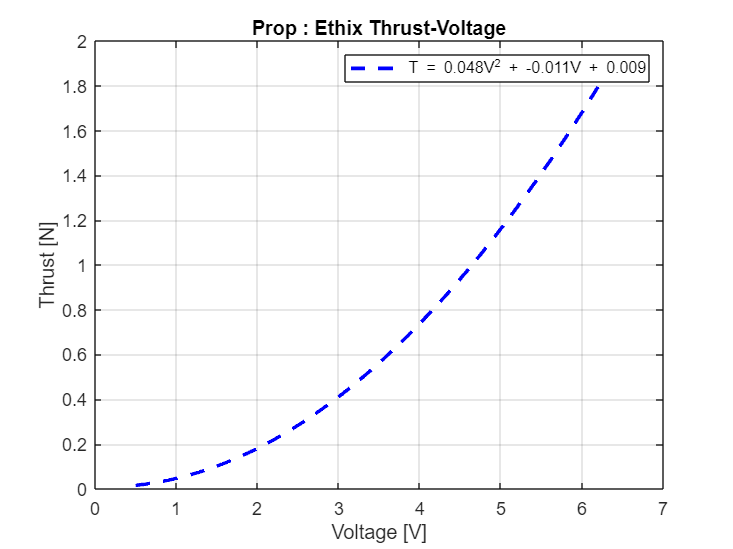

MotSim.plot_data()

Rotation = MotSim.Rotation()

Rotation =      1     0     0
     0     1     0
     0     0     1



F_thrust = MotSim.ForceExpression()

F_thrust =          0
         0
    1.8561


## Classe Dirigeable

box_keys = ["x_box_1", "x_box_2","y_box_1","y_box_2","z_box"];
box_values = [2.2, 1.8, 0.5, 0.7, 0.1];
box_containers = containers.Map(box_keys, box_values)

box_containers =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: double


D = Dirigeable(data, data_axes, angle, box_containers)

D =   Dirigeable with properties:

              Data: [5×1 containers.Map]
              Axes: [3×1 containers.Map]
             Angle: 0
    Box_Containers: [5×1 containers.Map]



W = D.weight()

W =          0
         0
  -29.4200


B = D.Buoyancy()

B =          0
         0
   84.0920


   8-------7

  /|      /|

 4-------3 |

 | |     | |

 | 5-----|-6

 |/      |/

 1-------2

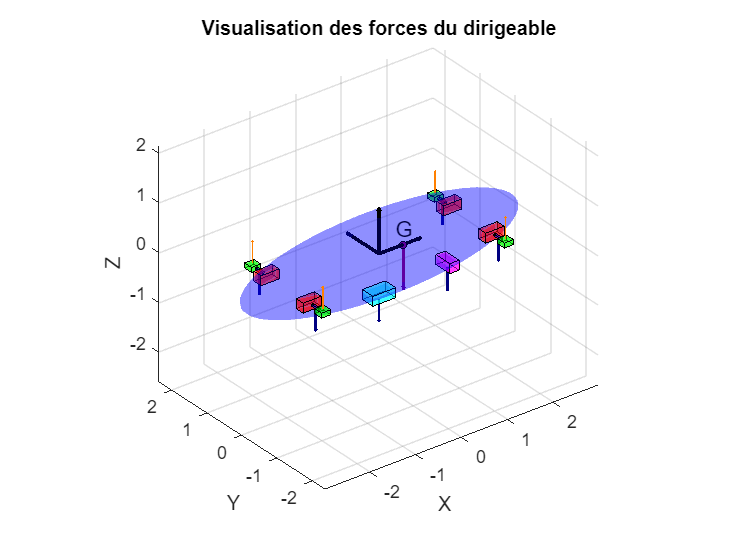

D.plot()